# Wind Turbine Capacity Factor Analysis

## Introduction

The following report analyses performance parameters of the *Post Oak Wind LLC* wind power plant (Plant ID: 56483), located near Abilene, TX (USA).

## 1. Identifying the plant

Using the form EIA 860, the plant has been identified to be located at (-99.656400, 32.514400). The wind turbines in the plant are mainly Gamesa G87-2.0 wind turbines with a hub height of 255 ft (or 77.724 m).

## 2. Annual Capacity Factor

The annual capacity factor is calculated as $\textrm{Capacity}\;\textrm{Factor}=\frac{\textrm{Actual}\;\textrm{Energy}\;\textrm{Output}}{\textrm{Maximum}\;\textrm{Energy}\;\textrm{Output}}$. 

The capacity of the plant (i.e. the maximum energy output in the given period) can be found by $\textrm{Max}\;\textrm{Energy}=\textrm{Hourly}\;\textrm{Power}\;\textrm{Capacity}*\frac{\textrm{Hours}}{\textrm{Period}}$ and in our case the period is defined as one year. The power rating of the plant is 200MW and hence the annual capacity can be found:

Capa = 200;                                 %MW from EIA 860
CapaAnnual = Capa*8760;                     %MWh/yr

Now, the actual energy output needs to be calculated. This is based on some physical parameters and some design parameters. The wind speed (${v_w }^3$) and the density of air ($\rho$), along with the swept area of the blades ($A$) are used to calculate the available power under the actuator disk model: $P_a =\frac{1}{2}\rho \;A\;{v_w }^3$.

Then, the actual power is found by $P_w =C_p \;P_a$, where $C_{p\;}$is the Power Coefficient, which describes how *"efficiently"* the power is exctracted from the wind and delivered to the rotor shaft.

The first step is, therefore, to define the operating and design parameters:

rho = 1.225;                                 %kg/m^3
diam = 87;                                   %m
radius = diam/2;                             %m
Area = pi()*(radius^2);                      %m^2

Prated = 2000000;                            %W source: https://www.nhsec.nh.gov/projects/2006-01/documents/13_gamesa.pdf
vwrated = 14;                                %m/s source: https://www.thewindpower.net/turbine_en_46_gamesa_g87-2000.php
cutin = 4;                                   %m/s source: https://www.nhsec.nh.gov/projects/2006-01/documents/13_gamesa.pdf
cutout = 25;                                 %m/s source: https://www.nhsec.nh.gov/projects/2006-01/documents/13_gamesa.pdf

To find $C_p$, the rated speed from the Technical Datasheet is used even if in reality the actual $C_p$ value varies based on wind speed. So, to get a single *equivalent constant* the following equation is used: $C_{p,\textrm{eq}} =\frac{{2\;P}_{\textrm{rated}} }{\rho \;A\;v_{w,\textrm{rated}}^3 }$. However, this profile presents a *jump* when *cut-in* speed is reached, resembling the behaviour of a switch-on mechanism, as shown in the left plot at the end of this Section when the velocity is *4 m/s*. To obtain a continuous profile (right plot at the end of the Section), which would resemble the real behaviour of "ramp-up" of the turbine, this equation would need to be adjusted to consider the *cut-in* treshold as $C_{p,\textrm{eq}} =\frac{{2\;P}_{\textrm{rated}} }{\rho \;A\;{\left(v_{w,\textrm{rated}} -v_{\textrm{cutin}} \right)}^3 }$.  To mantain the model simple, the unadjusted $C_p$ will be used and the *"switch-on"* model used, as an assumption to be noted.

Cp = 2*Prated/(rho*Area*(vwrated)^3);                         %Cp calculated from rated speed and adjusted for cutin
CpCut = 2*Prated/(rho*Area*(vwrated-cutin)^3);                %Cp calculated from rated speed and adjusted for cutin
CpAct = mean([0.4,0.426,0.436,0.439,0.435,0.412,0.365,0.305,0.247]);      %Cp calculated from turbine datasheet, referenced in next Section
fprintf("The Cp with the jump is %.2f, while the Cp smoothed to a continuous output is %.2f.",Cp, CpCut)

The Cp with the jump is 0.20, while the Cp smoothed to a continuous output is 0.55.

The wind data is extracted from [https://www.renewables.ninja/](https://www.renewables.ninja/) and is stored in hourly values in the relevant file. The recordings are accessed from the script

WindData = readmatrix('Wind Data.csv');
VwHourly = WindData(:,4);

Now, it is possible to estimate the power extracted from the wind during the year of operation (database from 2019) by assessing the following four regions:

- Below cut-in wind speed: $P=0\;W$

- Maximum Power Region: $P$ is calculated using the actuator disk model

- Rated Power Region: the rated power is reached and $P=P_{\textrm{rated}}$

- Above cut-out: $P=0\;W$

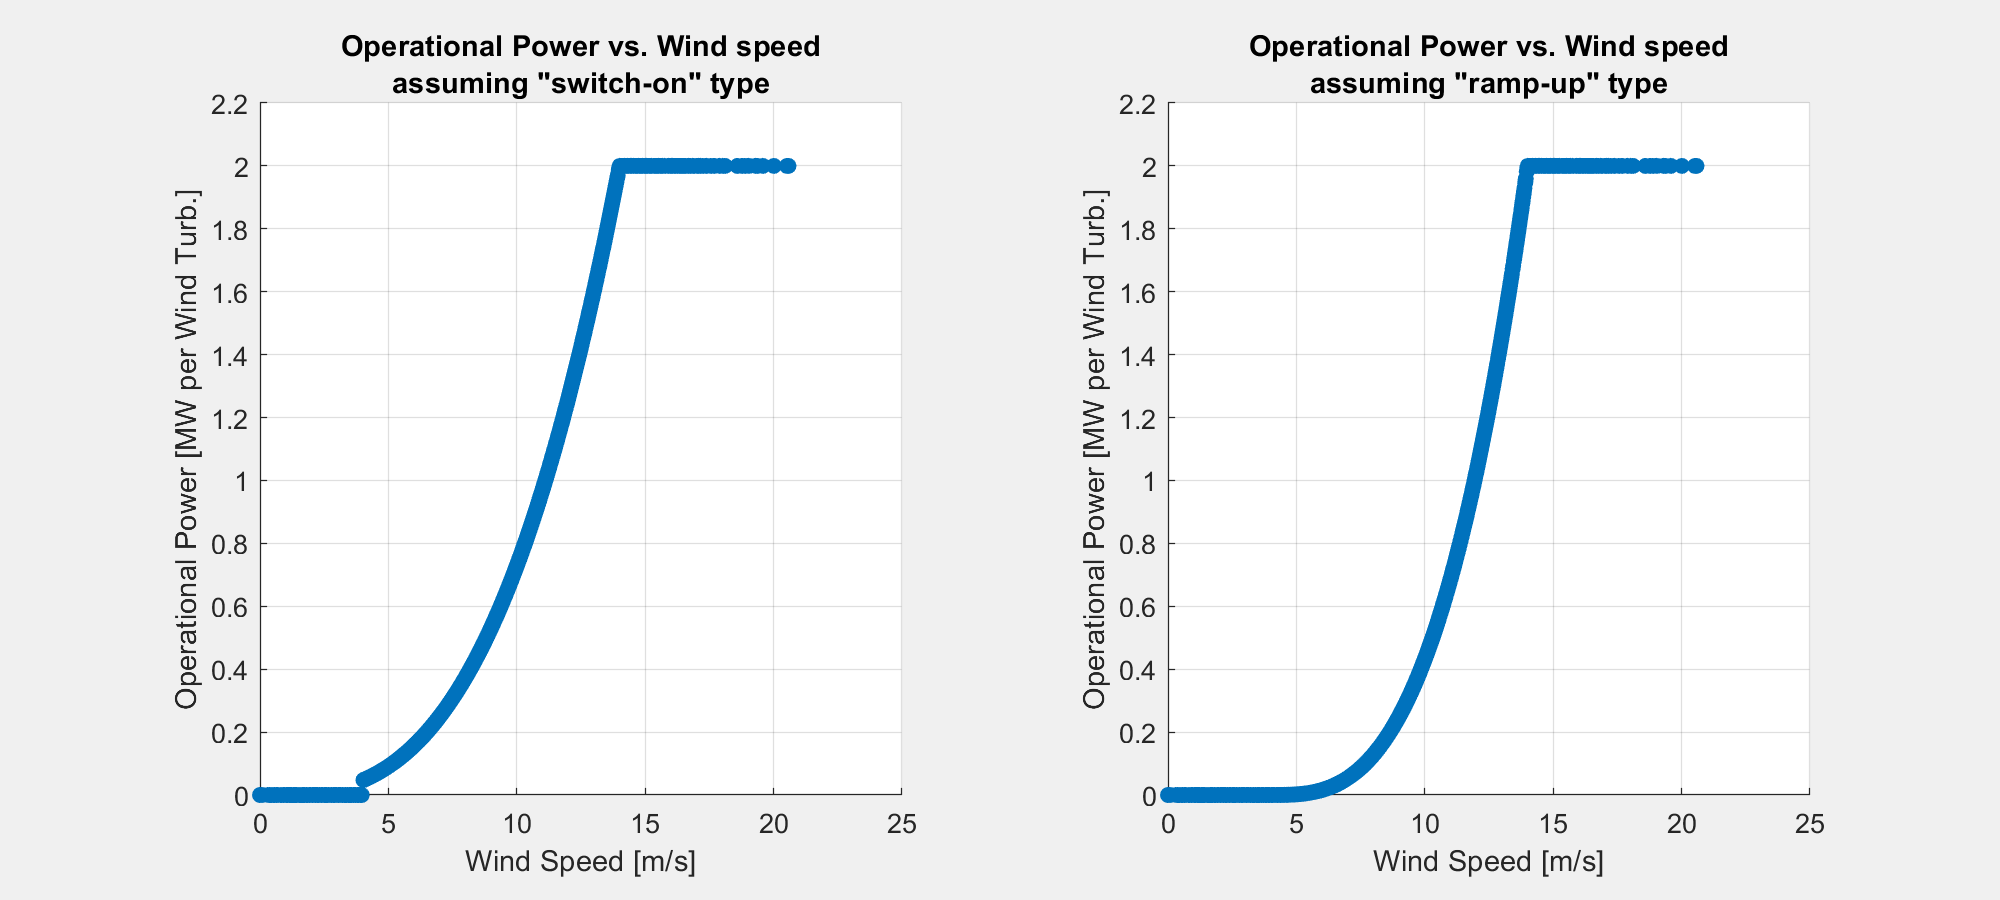

PowerEstimated = zeros(length(VwHourly),1);          %initialised array for power output
PowerEstimatedCut = zeros(length(VwHourly),1);          %initialised array for power output cutin considered
countPow = 0;                                        %counter for rated power hours
for i = 1:1:length(VwHourly)
    if VwHourly(i,1)<cutin                           %switched off if wind speed is below cut-in so nothing changes
    elseif VwHourly(i,1)<cutout                      %if above cutout, power is zero hence no if statement needed
        VwCube=(VwHourly(i,1))^3;                    %velocity cubed at each timestep
        VwCubeCut=(VwHourly(i,1)-cutin)^3;           %velocity cubed at each timestep considering cutin
        guessPower = Cp*0.5*rho*Area*(VwCube);       %power estimation [Wh]
        guessPowerCut = CpCut*0.5*rho*Area*(VwCubeCut);       %power estimation considering cutin [Wh]
        if VwHourly(i,1)>=vwrated                    %check if rated power is exceeded (and apply curtailment)
            PowerEstimated(i,1) = Prated;            %curtailed power
            PowerEstimatedCut(i,1) = Prated;         %curtailed power
            countPow = countPow+1;                   %count increment for curtailed operations
        else
            PowerEstimated(i,1) = guessPower;        %power if below rated
            PowerEstimatedCut(i,1) = guessPowerCut;  %power if below rated, cutin considered
        end
    end
end

f1 = figure(1); clf(f1)
set(f1,'Visible','on')
f1.Position = [100 100 1000 450];
tl1 = tiledlayout(f1,1,2); 

nexttile(tl1)
hold on
scatter(VwHourly,PowerEstimated/1000000, 'o', 'filled')
grid on
xlabel('Wind Speed [m/s]')
ylabel('Operational Power [MW per Wind Turb.]')
title({'Operational Power vs. Wind speed','assuming "switch-on" type'})
ylim([0 2.2])
yticks(0:0.2:2.2)
hold off
nexttile(tl1)
hold on
scatter(VwHourly,PowerEstimatedCut/1000000, 'o', 'filled')
xlabel('Wind Speed [m/s]')
ylabel('Operational Power [MW per Wind Turb.]')
title({'Operational Power vs. Wind speed','assuming "ramp-up" type'})
ylim([0 2.2])
yticks(0:0.2:2.2)
grid on
hold off

In the figure above, it is possible to see the behaviour of the power exctracted (i.e. before losses) as wind speed increases.

Currently, the power stored is for a single G87-2.0 turbine. It is possible to scale the value to the whole plant by multiplying this for the number of turbines present.

PwHourlyCalc = PowerEstimated*98;            %Wh
PwAnnualCalc = sum(PwHourlyCalc)/1000000;    %MWh/yr

fprintf("The annual power extracted from wind is %.3f MWh or %.2f GWh (before losses due to the generator and the transmission of power).\n",PwAnnualCalc,PwAnnualCalc/1000)

The annual power extracted from wind is 381329.937 MWh or 381.33 GWh (before losses due to the generator and the transmission of power).


Finally, the annual extracted power can be used as actual energy output from wind to find the capacity factor.

CapaFactorCalc = PwAnnualCalc/CapaAnnual;
fprintf("The Capacity Factor for the plant is %.2f%%", CapaFactorCalc*100)

The Capacity Factor for the plant is 21.77%

It is important to note that this capacity factor is defined using the power at the rotor shaft, before any gearbox or generator losses are accounted for (as defined in the Lectures).

## 3. Capacity Factor comparison

The EIA-923 dataset includes data for the net electricity generated by the plant. By using the equation for Capacity Factor introduced in Section 2, it is possible to evaluate the actual Capacity Factor and the difference from the estimated value from the previous Section. A capacity factor of 21.77% (from Section 2) lays on the lower boundary of typical Capacity Factors for onshore plants, and it seems an underestimate. Hence we expect a higher value from real data.

GrossGen = 532629;                            %MWh/yr from EIA 923 schedules 6-7
CapaFactorEIA = GrossGen/CapaAnnual;

fprintf("The net capacity factor from the EIA923 form is %.2f%%, %.2f%% more than the calculated factor in Section 2.\n", CapaFactorEIA*100, (CapaFactorEIA-CapaFactorCalc)*100)

The net capacity factor from the EIA923 form is 30.40%, 8.64% more than the calculated factor in Section 2.


The value used is the gross electricity generation before acocunting for energy used in the facility. However, there is still an adjustment to be made:

- The capacity factor from EIA 923 is calculated using the power output from the set of turbines, hence taking into account the efficiency of the gearbox ($\eta_{\textrm{gearbox}}$) and of the generator itself ($\eta_{\textrm{generator}}$). The capacity factor from Section 2, instead, takes the power value of the rotor shaft (i.e. before any losses due to gearbox and generator). Thereofre the adjusted EIA capcity factor to be compared with the value calculated would be ${\textrm{Capacity}\;\textrm{Factor}}_{\textrm{adj}} =\frac{\textrm{Capacity}\;\textrm{Factor}}{\eta_{\textrm{gearbox}} \eta {\;}_{\textrm{generator}} }$.

Assuming $\eta_{\textrm{gearbox}}$and $\eta_{\textrm{generator}}$ to be 0.9 and 0.85, respectively, the value of ${\textrm{Capacity}\;\textrm{Factor}}_{\textrm{adj}}$ can be found

etagear = 0.9;
etagen = 0.85;
CapaFactorEIAAdj = CapaFactorEIA/etagear/etagen;
fprintf("The adjusted capacity factor from the EIA923 form is %.2f%% (compared to %.2f%% calculated in Section 2).", CapaFactorEIAAdj*100, CapaFactorCalc*100);

The adjusted capacity factor from the EIA923 form is 39.74% (compared to 21.77% calculated in Section 2).

The reasons behind the discrepancy can be several, here the main ones are presented:

- The $C_p$ used in Section 2 is an estimated value. The modelling of the *continuous* vs *discountinouos* transition from below cut-in to maximum power region at the beginning of this section already shows how such a value can change. In reality, this value is even more complex and varies in the *maximum power regime*, affecting the actual power extracted from the wind. The $C_p$ profile for the G87-2.0 turbine as a function of wind speed is shown by the blue line in the next figure (source: Technical File FT002404 - Gamesa Eolìca). By calculating an average for $C_p$ from the actual values in the max power region (taken as $4\;m/s<v_w <14\;m/s$, and calculated in Section 1) allows to appreciate the wide difference between the models and reality and the effect of this value on the power output. A more complex model could allow to capture the behaviour correctly and is believed to be the biggest cause of discrepancy between calculated and measured value.

            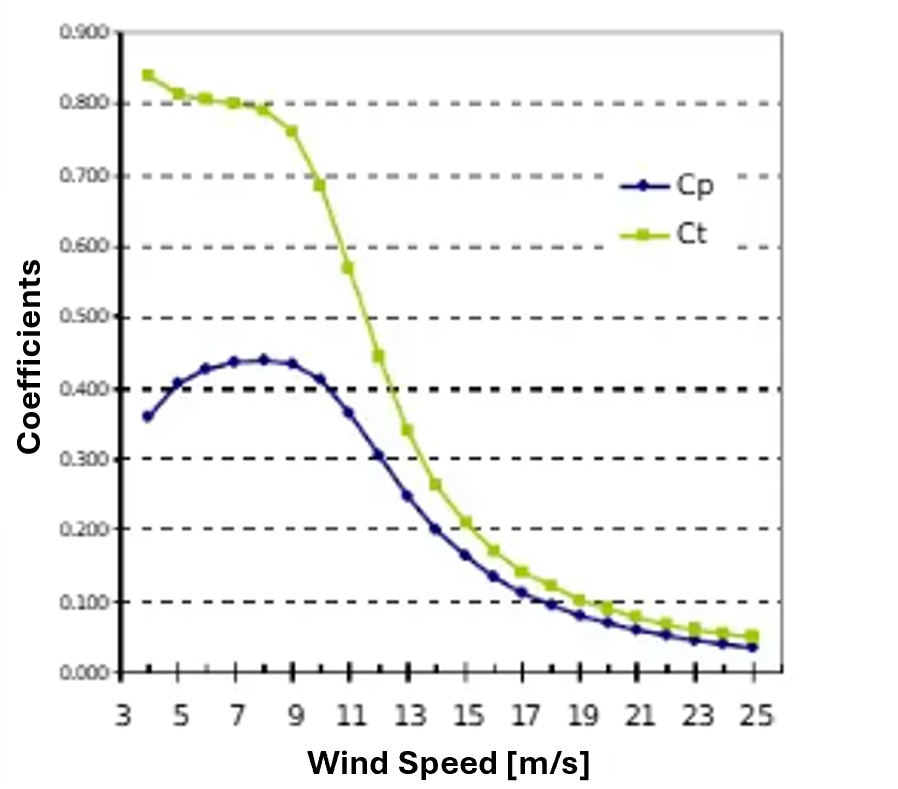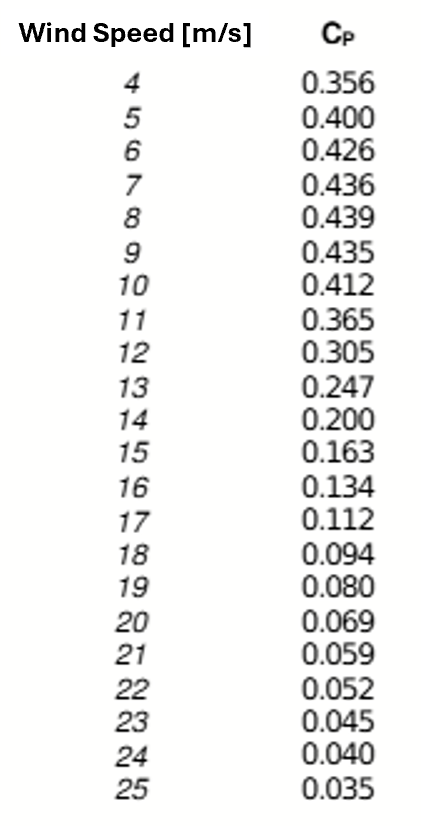

fprintf("The average Cp in the max power region is %.2f", CpAct)

The average Cp in the max power region is 0.39

- The actuator disk model presents the following assumptions which are clearly not realistic: (1) homogenous, incompressible, and steady state fluid flow; (2) an infinite number of blades; (3) uniform thrust over the disk or rotor area; (4) a nonrotating wake. By employing better models the discrepancy likely reduces further.

Additional minor differences can be due to the following reasons:

- Wind data is hourly, hence assuming the wind has a constant speed for the whole hour which is not realistic. Even by considering this value as an average, the differences of wind speeds in a given hour might be such that wind speed "changes" regime (i.e. might pass from 20 m/s to 26 m/s, enterig the cut-out region for several minutes) and this is not reflected in the power estimation.

- External conditions (i.e. maintenance, grid congestion, tests) may cause non-standard operation for minutes or hours, altering the real power output (this factor would mainly reduce power output, hence not very likely in this case).

## 4. Wind Speed PDF and Rated regime operation

The wind data can be analysed by means of a probability density function diagram. This is presented in the next figure, using bins size of 1 m/s.

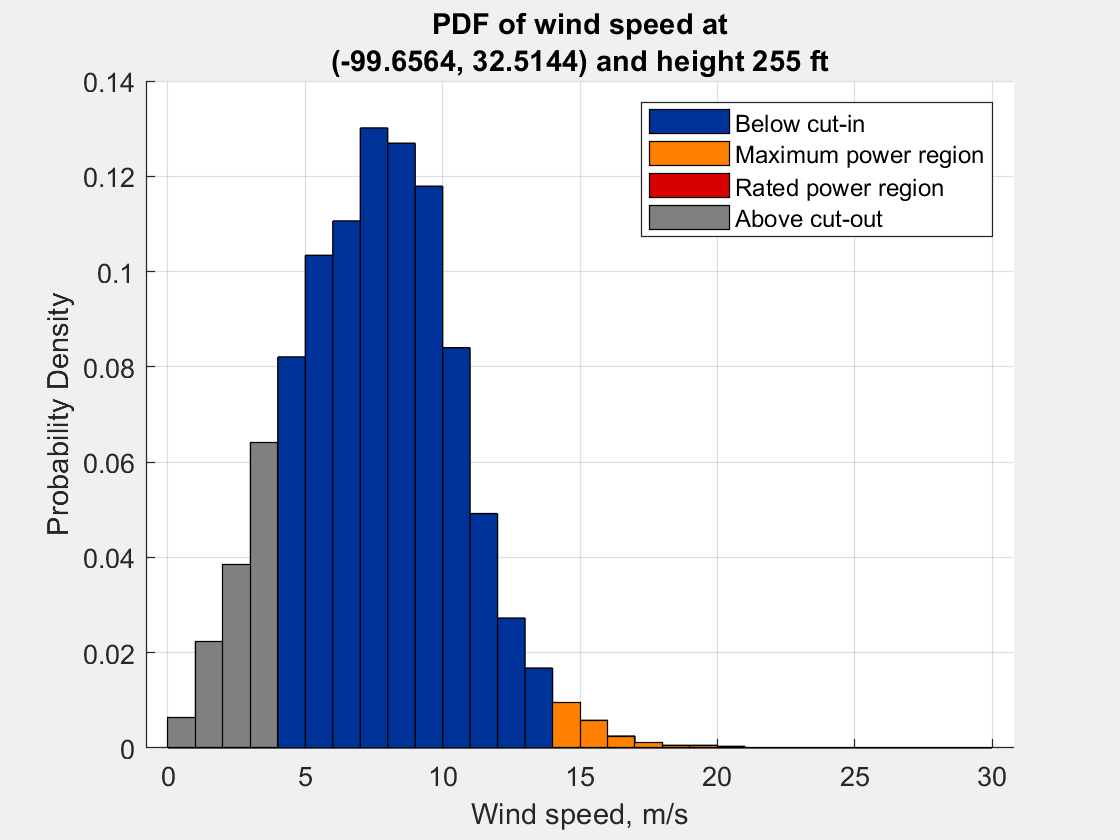

[counts, edges] = histcounts(VwHourly, 0:1:30, 'Normalization','pdf');
binCenters = edges(1:end-1) + diff(edges)/2;

f2 = figure(2); clf(f2)
set(f2,'Visible','on')
set(gcf,'ToolBar','none')
hold on

idx_orange = binCenters >= 14 & binCenters < 25;
idx_red = binCenters >= 25;
idx_gray = binCenters <=4;

bar(binCenters, counts, 1, 'FaceColor', [0 0.2 0.6]);
bar(binCenters(idx_orange), counts(idx_orange), 1, 'FaceColor', [1 0.5 0]);
bar(binCenters(idx_red), counts(idx_red), 1, 'FaceColor', [0.85 0 0]);
bar(binCenters(idx_gray), counts(idx_gray), 1, 'FaceColor', [0.5 0.5 0.5]);

xlabel('Wind speed, m/s')
ylabel('Probability Density')
title({'PDF of wind speed at','(-99.6564, 32.5144) and height 255 ft'})
grid on
legend({'Below cut-in', 'Maximum power region', 'Rated power region', 'Above cut-out'}, 'Location', 'northeast')
hold off
exportgraphics(f2, 'wind_speed_pdf.png')

The plot shows in gray the velocities below *cut-in*, in blue the *maximum power region*, in orange the *rated power* operations, and in red (not visible) the velocities above *cut-out*.

In Section 2, when the power is calculated, a counter is used to determine the amount of hours spent in the *rated power regime* during the year.

fprintf('The plant operated for %d out of 8760 hours at rated power.\nThis is equivalent to %.2f%%, which appears to be in line with the cumulative density of the orange region.', countPow, countPow/8760*100);

The plant operated for 179 out of 8760 hours at rated power.
This is equivalent to 2.04%, which appears to be in line with the cumulative density of the orange region.

## 5. Increased Rated Power operations

By increasing the rated power of the wind turbine, it is possible to analyse the effect on power output and capacity factor. Here, the rated power of all the wind turbines of the plant is increasead by 500kW each step and the resulting additional power (calculated as $\Delta P=P_w \left(\textrm{new}\;\textrm{rating}\right)-P_w \left(2\;MW\right)$) and Capacity Factor of the plant are plotted.

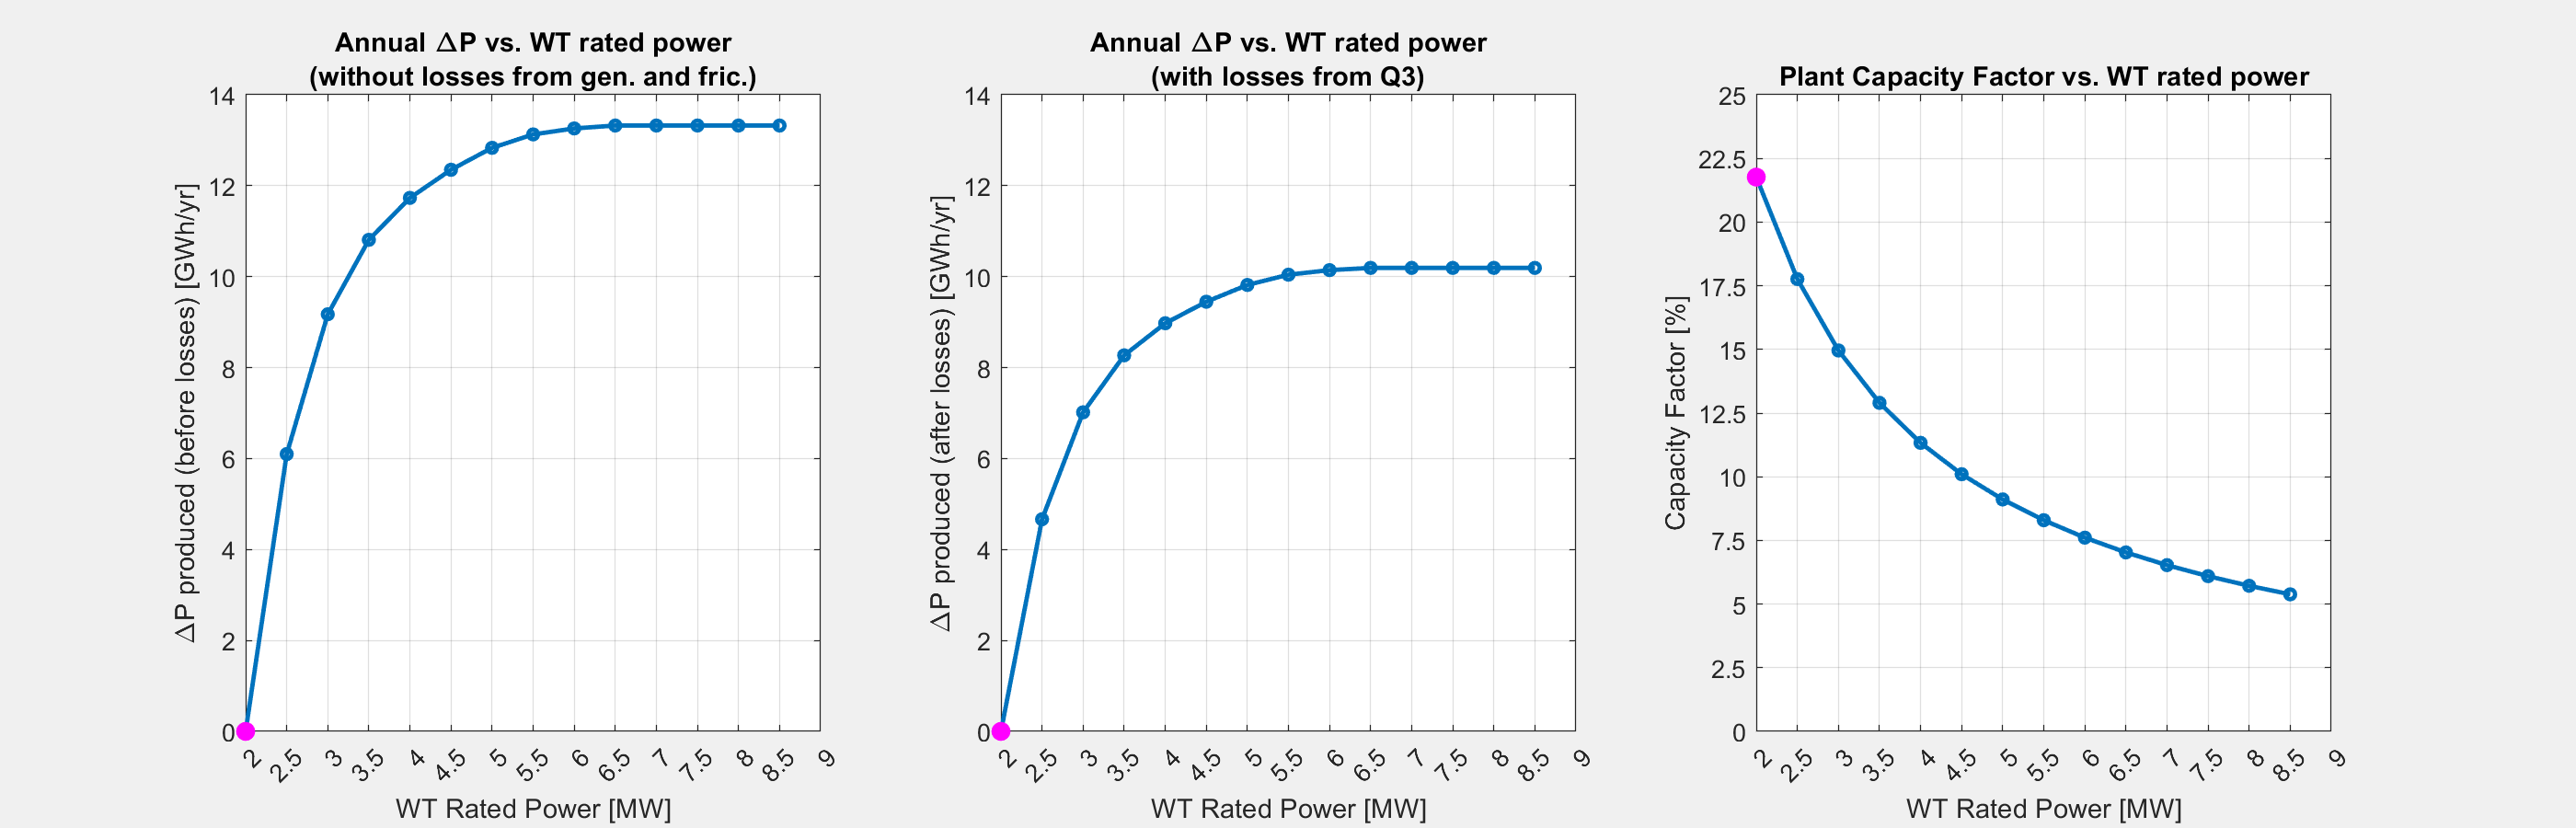

steps = 14;                                                     %amount of power additions checked
Delta = zeros(steps,1);
CF = zeros(steps,1);
RatedPowerWT = zeros(steps,1); 
t = Prated/(vwrated^3);                                         %Constant equivalent to 0.5*Cp*rho*Area
for k = 1:steps
    Pratedk = 2000000+500000*(k-1);                             %power rating stepping up 500kW each iteration starting from base case 2MW
    vwratedk = (Pratedk/t)^(1/3);                               %rated wind speed for each Power rating, assuming same behaviour as 2MW WT
    PowerEstimatedk = zeros(length(VwHourly),1);                %initialised array for power output
    for i = 1:1:length(VwHourly)
        if VwHourly(i,1)<cutin                       
            PowerEstimatedk(i,1) = 0;                           %switched off if wind speed is below cut-in
        elseif VwHourly(i,1)<cutout
            VwCube=(VwHourly(i,1))^3;                           %velocity cubed at each timestep
            guessPowerk = t*(VwCube);       %power with Cp from datasheet [Wh]
            if VwHourly(i,1)>=vwratedk                          %check if rated power is exceeded (and apply curtailment)
                PowerEstimatedk(i,1) = Pratedk;                 %curtailed power
            else
                PowerEstimatedk(i,1) = guessPowerk;       %power if below rated
            end
        else
            PowerEstimatedk(i,1) = 0;                           %switched off is wind speed exceeds cut-out
        end
    end
    PwHourlyCalck = PowerEstimatedk*98;                   %Wh
    PwAnnualCalck = sum(PwHourlyCalck)/1000000;           %MWh/yr
    DeltaPowerAnnual = (PwAnnualCalck-PwAnnualCalc)/1000; %GWh/yr
    CapaAnnualk = CapaAnnual+((Pratedk-Prated)*98*8760/1000000); %MWh/yr
    CapaFactorCalck = PwAnnualCalck/CapaAnnualk;
    RatedPowerWT(k,1) = Pratedk/1000000;                        %MW
    Delta(k,1) = DeltaPowerAnnual;
    CF(k,1) = CapaFactorCalck;
end


xs = RatedPowerWT;
ys1 = Delta;
ys2 = CF*100;

f3 = figure(3); clf(f3)
set(f3,'Visible','on')
f3.Position = [100 100 1400 450];
tl = tiledlayout(f3,1,3);

nexttile(tl);  plot(xs,ys1,'-o','LineWidth',1.8,'MarkerSize',4); hold on
scatter(2,0,60,'magenta','filled'); hold off
grid on; box on
xlabel('WT Rated Power [MW]')
ylabel('\DeltaP produced (before losses) [GWh/yr]')
title({'Annual \DeltaP vs. WT rated power','(without losses from gen. and fric.)'})
xticks(2:0.5:9); xlim([2 9])
ylim([0 14])

nexttile(tl);  plot(xs,ys1*etagear*etagen,'-o','LineWidth',1.8,'MarkerSize',4); hold on
scatter(2,0,60,'magenta','filled'); hold off
grid on; box on
xlabel('WT Rated Power [MW]')
ylabel('\DeltaP produced (after losses) [GWh/yr]')
title({'Annual \DeltaP vs. WT rated power','(with losses from Q3)'})
xticks(2:0.5:9); xlim([2 9])
ylim([0 14])

nexttile(tl);  plot(xs,ys2,'-o','LineWidth',1.8,'MarkerSize',4); hold on
scatter(2,ys2(1),60,'magenta','filled'); hold off
grid on; box on
xlabel('WT Rated Power [MW]')
ylabel('Capacity Factor [%]')
title('Plant Capacity Factor vs. WT rated power')
xticks(2:0.5:9); xlim([2 9])
yticks(0:2.5:25); ylim([0 25])

The magenta point represents the starting Wind Turbine model (rated at 2000 kW) in both cases. The cut-in velocity is kept constant at 4m/s and the cut-out at 25 m/s. the maximum rated speed tested remains below 25 m/s hence allow the model to run.

Analysing the results, increasing capacity comes with advantages and disadvantages. Starting with the evident conclusions, the main advantage is that a **higher power** is produced by increasing the rating since more of the high-speed wind energy can be effectively captured. 

To summarise better the advantages:

- More energy is captured and produced until rating hits 6.5MW, hence more energy can be sold and **higher revenues** produced

- The utilisation of high-wind period is improved (i.e. better use of the wind power available)

- In Texas, high demand periods are more and more frequent (due to extreme weather) and high temperature are often happening at the same time as strong hot winds, with higher rating this energy can be efficiently captured

The disadvantages to this operation can be summarised as follows:

- The additional power captured is always less than the added capacity, resulting in a **decrease of Capacity Factor**.

- Clearly the extractable power plateaus after 4.5 MW of added rating to each turbine (at 6.5 MW total), signifying that the high-speed wind energy has been all captured. In addition, the added power per step slows down significantly after 1 MW of added rating to each WT.

- The grid integration could critically impact the operations at high-speed wind and result in curtailment, this would virtually eliminate all the benefits of uprating

- The cost of the equipment is another critical downside of this: increasing the rating comes with huge costs to fit a better generator, stronger components, better power systems, and every other upgraded component. This additional cost would have to be quantified and then compared to the added revenue coming from selling the additional electricity.